%Solar parameters
% A = 34; %Area of panel in meter square
% seff = 0.16; %Solar panel efficiency in %
% MaxSP = 5; %Maximum solar power in KW
% NSP = 7; %Number of Solar panels

% %Wind Parameters
% vc = 3; %Cut-in velocity in m/s
% vf = 25; %Cut-off velocity in m/s
% vr = 12; %Rated speed in m/s
% MaxWP = 5; %Maximum wind power in KW
% NWP = 8; %Number of wind turbines

% %Battery parameters
% BLmax = 36; %Maximum energy level in KWh
% BLmin = 7.2; %Minimum energy level in KWh
% BLv = 18; %Initial energy level in KWh
% Crate = 4; %Maximum charging rate in KWh
% Drate = -4; %Maximum discharging rate in KWh
% 

% load = randi(45,1000,24)  %Load Profile for 1000 days

% SI = rand(1000,24)  % Solar Irradiance for 1000 days in KW/m2

% V = randi(10,1000,24)   % Wind Velocity for 1000 days in m/s

% Price = randi(40,24,1)   % Price distribution over 24 hours in cents/hour

% PV = NSP*seff*A*SI;    %Solar energy across 1000 days per hour for given number of panels

% max(Wind)

% % for days = 1:1000
% %     for hours = 1:24
% %         v = V(days,hours);
% %         
% %         if(vf <= v || vc >=vf)
% %             Wind(days,hours) = 0; 
% %         end
% % if(vc<=v && v<=vr)
% %     Wind(days,hours) = (MaxWP*((v^3)-(vc^3)))/((vr^3)-(vc^3));
% % end
% % if(vr<=v && v<=vf)
% %     Wind(days,hours) = MaxWP;
% %     
% % end
% %     end
% % end

% Wind = NWP*Wind;
% Wind

## Observations and Action Specifications

The observations from the environment are Load profile, PV Production, Wind Production, SOC,  Time.

% v = zeros(140,1);
% c = -20;
% for i=1:20
%     v(i) = c;
%     c = c+1;
%     
% end
% v(21) = 0;
% for i=22:140
%     v(i)=i-21;
%     
% end
% v

v = zeros(100,1);
for i=1:100
    v(i) = i;
end

v

v =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


ObservationInfo = rlFiniteSetSpec(v);
ObservationInfo.Name = 'MicroGrid States';
ObservationInfo.Description = 'SOC';

The environment has a discrete action space where the agent can apply one of three possible charging/discharging rates to the Battery: -4, 0, 4. 4 is the maximum charging or discharging rates.

ActionInfo = rlFiniteSetSpec([-1 0 1]);
ActionInfo.Name = 'Microgrid Action';

## Create Environment Using Function Names

To define a custom environment, first specify the custom `step` and `reset` functions. These functions must be in your current working folder or on the MATLAB path.

The custom `reset` function sets the default state of the environment. This function must have the following signature.

[InitialObservation,LoggedSignals] = myResetFunction()

To pass information from one step to the next, such as the environment state, use `LoggedSignals`. For this example, `LoggedSignals` contains the states of the cart-pole environment: the position and velocity of the cart, the pendulum angle, and the pendulum angle derivative. The `reset` function sets the cart angle to a random value each time the environment is reset.

For this example, use the custom reset function defined in `myResetFunction.m`.

type myResetFunction.m;

function [InitialObservation,LoggedSignal] = myResetFunction()
%UNTITLED Summary of this function goes here
%   Reset function to place the custom Micro-grid environment into a
%   Random initial State
L0 = randi(45,1);
PV0 = randi(38,1);
Wind0 = randi(23,1);
SOC0 = 50;
t0 = 0;


% Return initial environment state variables as logged signals
LoggedSignal.State = [L0;PV0;Wind0;SOC0;t0;];
obs = SOC0;
InitialObservation = obs;
end



The custom `step` function specifies how the environment advances to the next state based on a given action. This function must have the following signature.

To get the new state, the environment applies the dynamic equation to the current state stored in `LoggedSignals`, which is similar to giving an initial condition to a differential equation. The new state is stored in `LoggedSignals` and returned as an output.

For this example, use the custom step function defined in `myStepFunction.m`. For implementation simplicity, this function redefines physical constants, such as the cart mass, every time `step` is executed.

type myStepFunction.m

function [NextObs,Reward, IsDone, LoggedSignals] = myStepFunction(Action, LoggedSignals)
%UNTITLED2 Summary of this function goes here
%   Custom Step function to construct MicroGrid for the
%   function
%   This function applies the given action to the environment and evaluates
%   the system dynamics for simulation step


%   Define the environment constants
deltat = 1;
Crate = 4;
Drate = -4;
%BLmax = 36; %Maximum energy level in KWh
%BLmin = 7.2; %Minimum energy level in KWh


%   Check if the given action is valid.
if ~ismember(Action,[-1, 0, 1])
    error('Action must be %g for charging and %g for idle and %g for discharging.',...
        -1,0,1);
end


%   Unpack the state vector from the logged signals.
State = LoggedSignals.State;
load = State(1);
pv = State(2);
wind = State(3);
soc = State(4);
time = State(5);

bprice = 2;
cprice = 2;

%Calculate PG(t)
u = Action*Crate;
PG = load - pv - wind + u;

load = randi(45,1);
pv = randi(38,1);
wind = randi(23,1);
time = time + 1;



% 

env = rlFunctionEnv(ObservationInfo,ActionInfo,'myStepFunction','myResetFunction')

env =   rlFunctionEnv with properties:

          StepFcn: 'myStepFunction'
         ResetFcn: 'myResetFunction'
    LoggedSignals: [1×1 struct]


## Validate Custom Functions

Before you train an agent in your environment, the best practice is to validate the behavior of your custom functions. To do so, you can initialize your environment using the `reset` function and run one simulation step using the `step` function. For reproducibility, set the random generator seed before validation.

Validate the environment created using function names.

rng(0);ObservationInfo
InitialObs = reset(env)

InitialObs = 50

[NextObs,Reward,IsDone,LoggedSignals] = step(env,-1);
NextObs

NextObs = 46

obsInfo = getObservationInfo(env)

obsInfo =   rlFiniteSetSpec with properties:

       Elements: [100×1 double]
           Name: "MicroGrid States"
    Description: "SOC"
      Dimension: [1 1]
       DataType: "double"


actInfo = getActionInfo(env)

actInfo =   rlFiniteSetSpec with properties:

       Elements: [3×1 double]
           Name: "Microgrid Action"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


rng(0)

dnn = [
    featureInputLayer(obsInfo.Dimension(1),'Normalization','none','Name','state')
    fullyConnectedLayer(24,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(24, 'Name','CriticStateFC2')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(length(actInfo.Elements),'Name','output')];

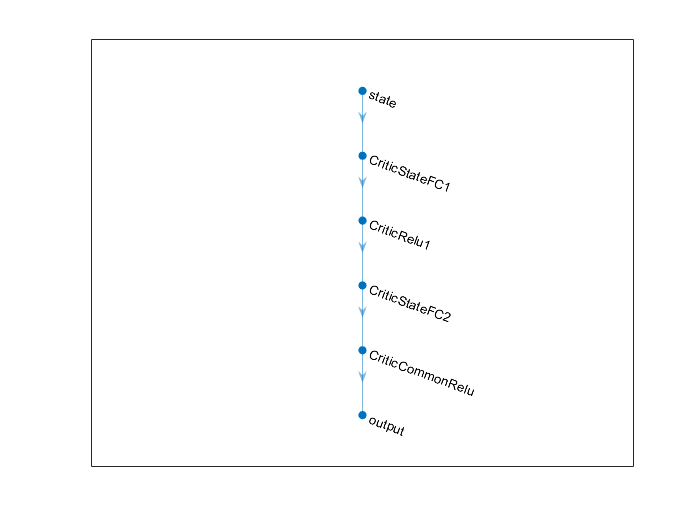

figure
plot(layerGraph(dnn))

criticOpts = rlRepresentationOptions('LearnRate',0.001,'GradientThreshold',1);

critic = rlQValueRepresentation(dnn,obsInfo,actInfo,'Observation',{'state'},criticOpts);

agentOpts = rlDQNAgentOptions(...
    'UseDoubleDQN',false, ...    
    'TargetSmoothFactor',1, ...
    'TargetUpdateFrequency',4, ...   
    'ExperienceBufferLength',100000, ...
    'DiscountFactor',0.99, ...
    'MiniBatchSize',256);

agent = rlDQNAgent(critic,agentOpts);

trainOpts = rlTrainingOptions(...
    'MaxEpisodes',1000, ...
    'MaxStepsPerEpisode',500, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',480); 


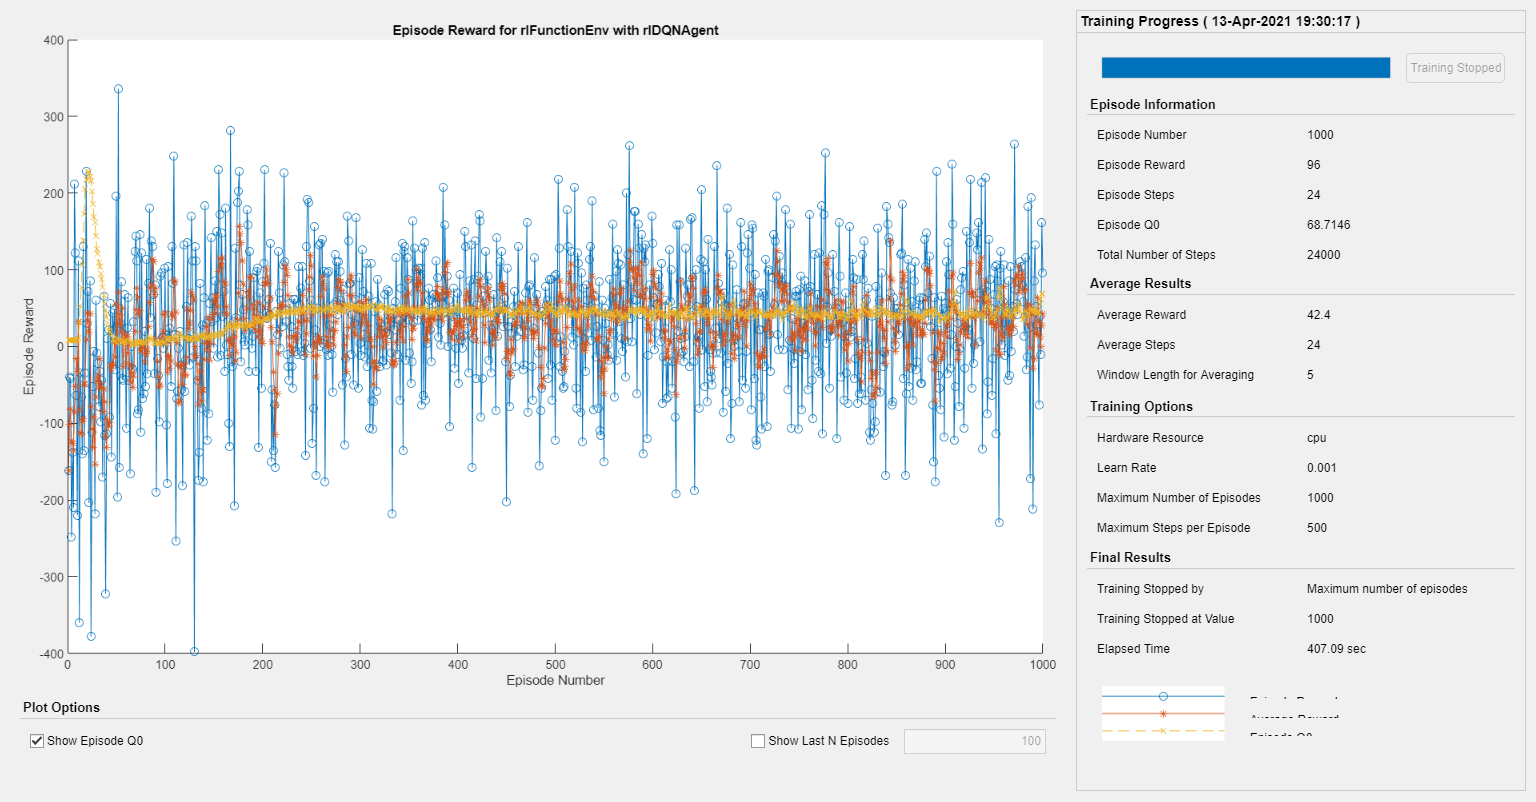

doTraining = true;
if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
end

qTable = rlTable(getObservationInfo(env),getActionInfo(env));
qRepresentation = rlQValueRepresentation(qTable,getObservationInfo(env),getActionInfo(env));
qRepresentation.Options.LearnRate = 1;

agentOpts = rlQAgentOptions;
agentOpts.EpsilonGreedyExploration.Epsilon = .04;
qAgent = rlQAgent(qRepresentation,agentOpts);

trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 50;
trainOpts.MaxEpisodes= 1000;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 450;
trainOpts.ScoreAveragingWindowLength = 30;

agentOpts = rlQAgentOptions;
agentOpts.EpsilonGreedyExploration.Epsilon = .04;
qAgent = rlQAgent(qRepresentation,agentOpts);

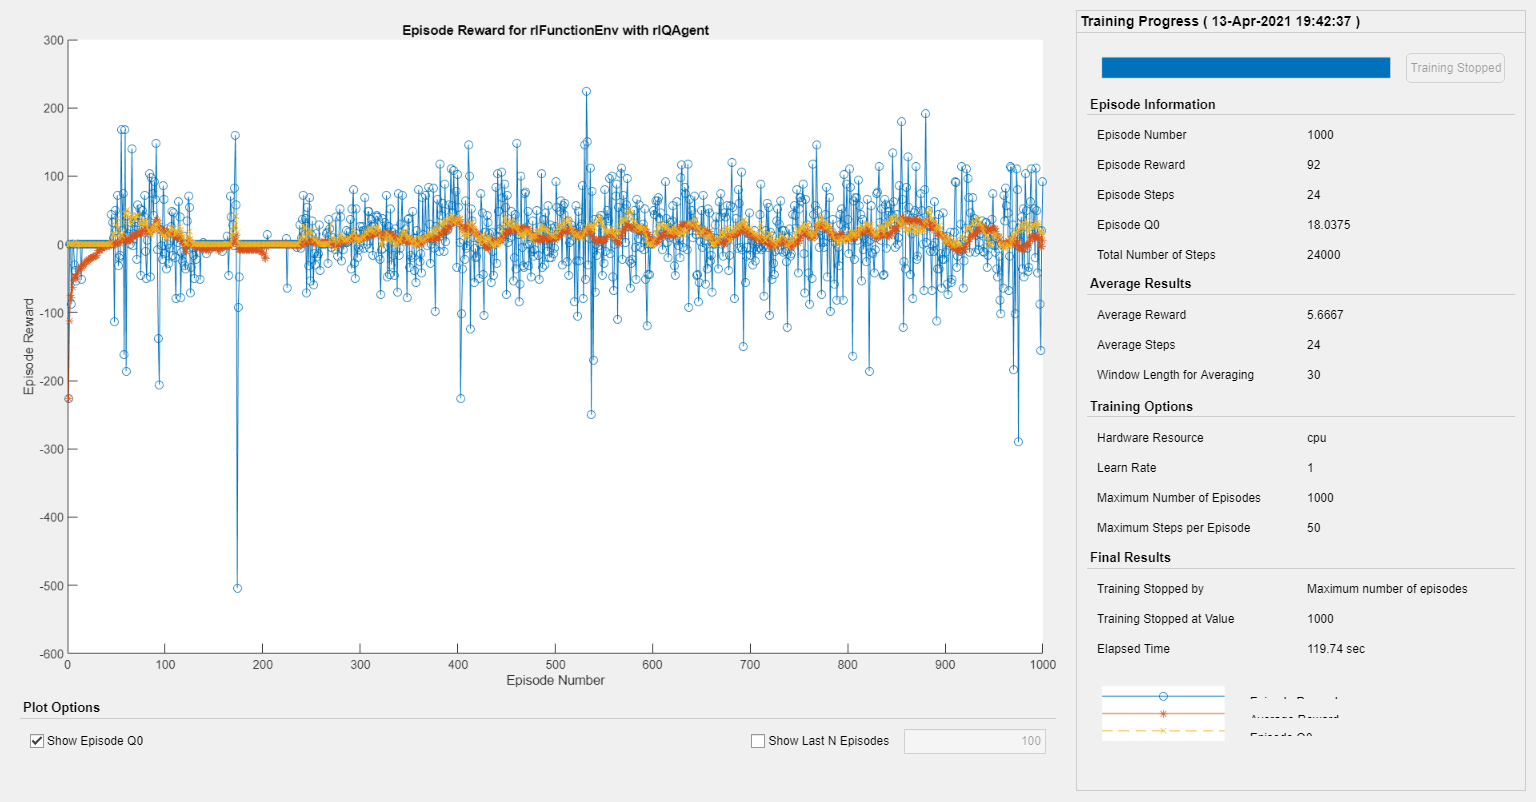

trainingStats = train(qAgent,env,trainOpts);

trainingStats

trainingStats = struct with fields:
       EpisodeIndex: [1000×1 double]
      EpisodeReward: [1000×1 double]
       EpisodeSteps: [1000×1 double]
      AverageReward: [1000×1 double]
       AverageSteps: [1000×1 double]
    TotalAgentSteps: [1000×1 double]
        Information: [1×1 struct]
          EpisodeQ0: [1000×1 double]
     SimulationInfo: [1000×1 struct]


agentOpts = rlSARSAAgentOptions;
agentOpts.EpsilonGreedyExploration.Epsilon = 0.04;
sarsaAgent = rlSARSAAgent(qRepresentation,agentOpts);

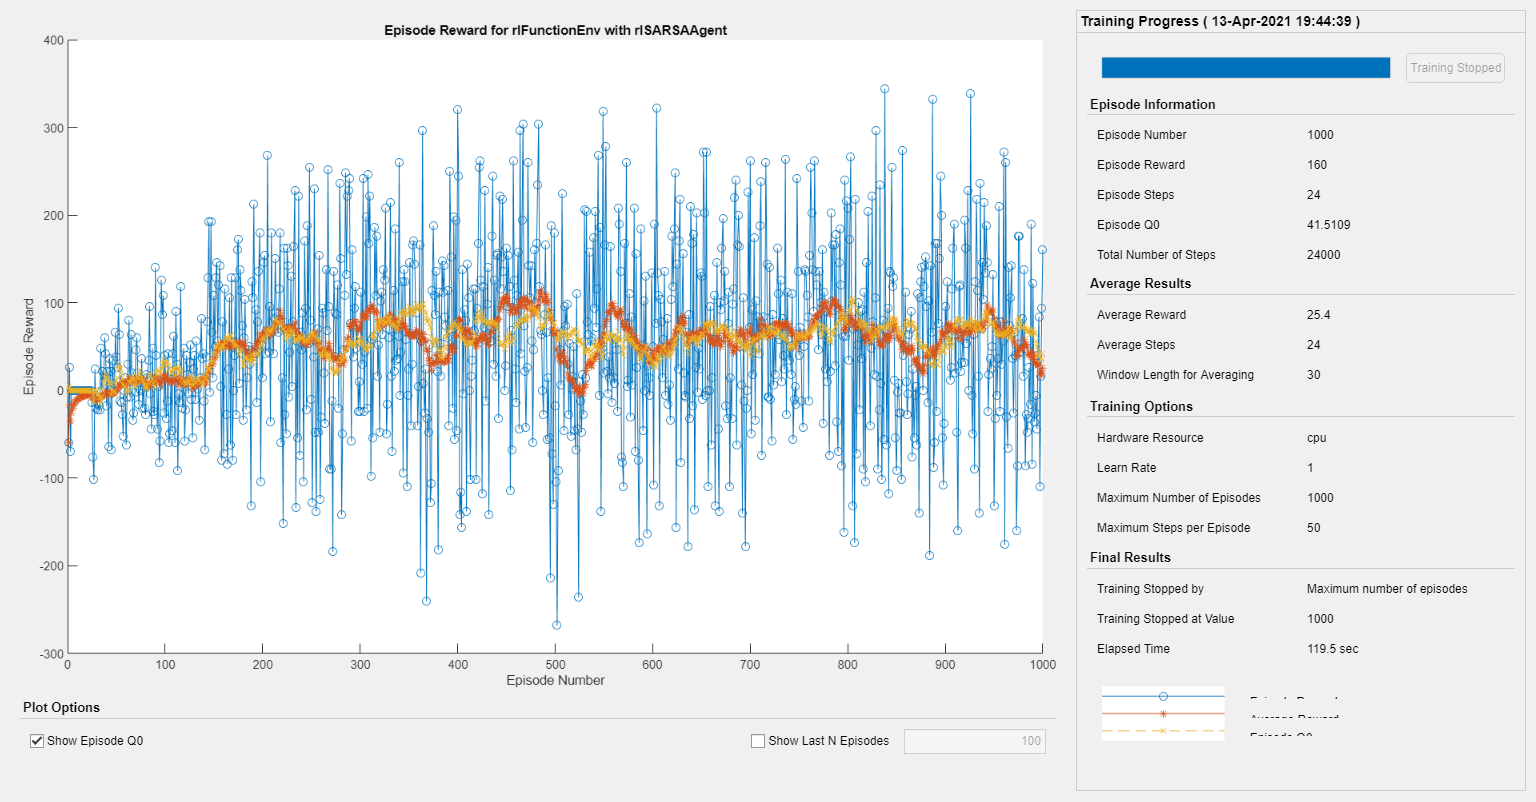

trainingStats = train(sarsaAgent,env,trainOpts);